7.3

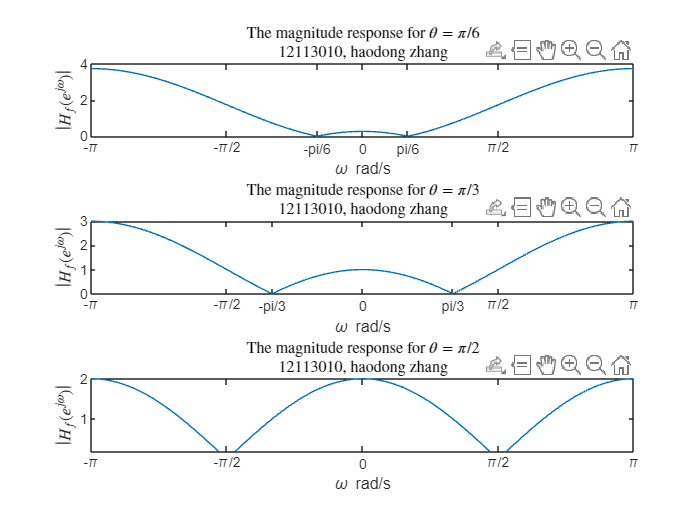

w = -pi:0.01:pi;
theata = [pi/6,pi/3,pi/2];
H = {};
for i=1:length(theata)
    H{i} = 1-2*cos(theata(i)).*exp(-1j*w)+(exp(-1j*2*w));
end
subplot(3,1,1);
plot(w,abs(H{1}));
title(['The magnitude response for $\theta=\pi/6$' newline '12113010, haodong zhang'], 'Interpreter', 'latex');
xlabel('\omega rad/s');
ylabel('$\left | H_f(e^{j\omega})  \right | $', 'Interpreter', 'latex')
xlim([-pi,pi])
xticks([-pi -pi/2 -pi/6 0 pi/6 pi/2 pi]);
xticklabels({'-\pi' '-\pi/2' '-pi/6' '0' 'pi/6' '\pi/2' '\pi'});
subplot(3,1,2);
plot(w,abs(H{2}));
title(['The magnitude response for $\theta=\pi/3$' newline '12113010, haodong zhang'], 'Interpreter', 'latex');
xlabel('\omega rad/s');
ylabel('$\left | H_f(e^{j\omega})  \right | $', 'Interpreter', 'latex')
xlim([-pi,pi])
xticks([-pi -pi/2 -pi/3 0 pi/3 pi/2 pi]);
xticklabels({'-\pi' '-\pi/2' '-pi/3' '0' 'pi/3' '\pi/2' '\pi'});
subplot(3,1,3);
plot(w,abs(H{3}));
title(['The magnitude response for $\theta=\pi/2$' newline '12113010, haodong zhang'], 'Interpreter', 'latex');
xlabel('\omega rad/s');
ylabel('$\left | H_f(e^{j\omega})  \right | $', 'Interpreter', 'latex')
xlim([-pi,pi])
xticks([-pi -pi/2 0 pi/2 pi]);
xticklabels({'-\pi' '-\pi/2' '0' '\pi/2' '\pi'});

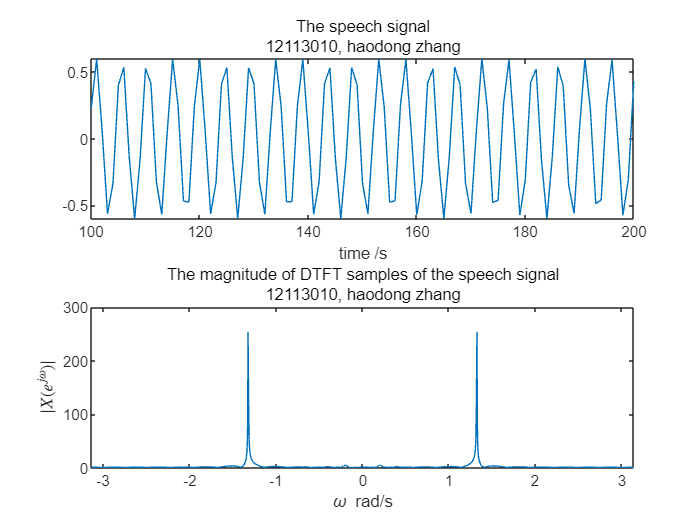

figure;
load nspeech1.mat;
% sound(nspeech1);
subplot(2,1,1)
plot(nspeech1);
xlim([100,200]);
title(['The speech signal' newline '12113010, haodong zhang']);
xlabel('time /s');

[X,w] = DTFT(nspeech1(100:1100),0);
subplot(2,1,2)
plot(w,abs(X));
xlim([-pi,pi]);
title(['The magnitude of DTFT samples of the speech signal' newline '12113010, haodong zhang']);
xlabel('\omega rad/s');
ylabel('$\left | X(e^{j\omega})  \right | $', 'Interpreter', 'latex');

[Xmax,Imax] = maxk(abs(X),2)

Xmax =   254.2287  254.2287


Imax =    297   729


theata = w(Imax)

theata =    -1.3254    1.3254


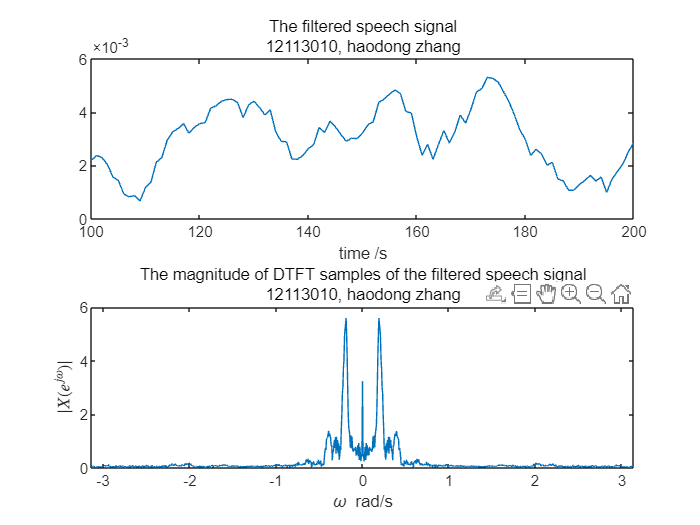

figure;
out = FIRfilter(nspeech1);
% sound(out);
subplot(2,1,1)
plot(out);
xlim([100,200]);
title(['The filtered speech signal' newline '12113010, haodong zhang']);
xlabel('time /s');

[X,w] = DTFT(out(100:1100),0);
subplot(2,1,2)
plot(w,abs(X));
xlim([-pi,pi]);
title(['The magnitude of DTFT samples of the filtered speech signal' newline '12113010, haodong zhang']);
xlabel('\omega rad/s');
ylabel('$\left | X(e^{j\omega})  \right | $', 'Interpreter', 'latex');

[Xmax,Imax] = max(abs(X));
theata = w(Imax);

7.4

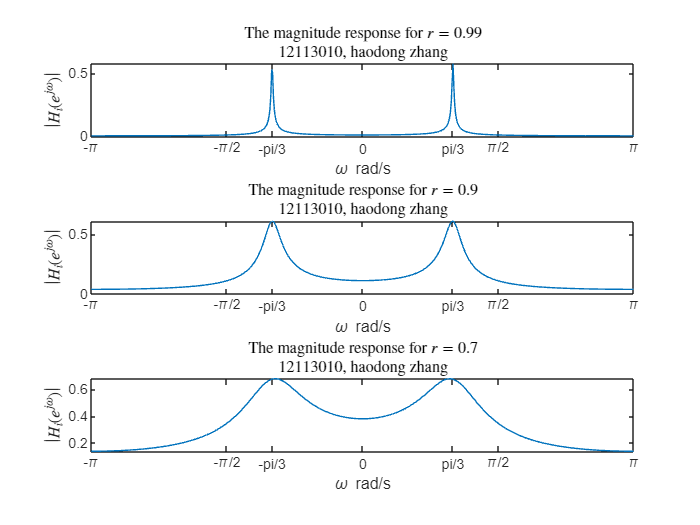

figure;
w = -pi:0.01:pi;
r = [0.99,0.9,0.7];
H = {};
for i=1:length(r)
    H{i} = (1-r(i))./(1-2*r(i)*cos(pi/3)*exp(-1j*w)+(r(i))^2*exp(-1j*2*w));
end
subplot(3,1,1);
plot(w,abs(H{1}));
title(['The magnitude response for $r=0.99$' newline '12113010, haodong zhang'], 'Interpreter', 'latex');
xlabel('\omega rad/s');
ylabel('$\left | H_i(e^{j\omega})  \right | $', 'Interpreter', 'latex')
xlim([-pi,pi])
xticks([-pi -pi/2 -pi/3 0 pi/3 pi/2 pi]);
xticklabels({'-\pi' '-\pi/2' '-pi/3' '0' 'pi/3' '\pi/2' '\pi'});
subplot(3,1,2);
plot(w,abs(H{2}));
title(['The magnitude response for $r=0.9$' newline '12113010, haodong zhang'], 'Interpreter', 'latex');
xlabel('\omega rad/s');
ylabel('$\left | H_i(e^{j\omega})  \right | $', 'Interpreter', 'latex')
xlim([-pi,pi])
xticks([-pi -pi/2 -pi/3 0 pi/3 pi/2 pi]);
xticklabels({'-\pi' '-\pi/2' '-pi/3' '0' 'pi/3' '\pi/2' '\pi'});
subplot(3,1,3);
plot(w,abs(H{3}));
title(['The magnitude response for $r=0.7$' newline '12113010, haodong zhang'], 'Interpreter', 'latex');
xlabel('\omega rad/s');
ylabel('$\left | H_i(e^{j\omega})  \right | $', 'Interpreter', 'latex')
xlim([-pi,pi])
xticks([-pi -pi/2 -pi/3 0 pi/3 pi/2 pi]);
xticklabels({'-\pi' '-\pi/2' '-pi/3' '0' 'pi/3' '\pi/2' '\pi'});

figure;
load pcm.mat;
sound(pcm);
subplot(3,1,1);
plot(pcm);
xlim([100,200]);
title(['The speech signal' newline '12113010, haodong zhang']);
xlabel('time /s');

[X,w] = DTFT(pcm(100:1100),10000);
subplot(3,1,2);
plot(w,abs(X));
xlim([-pi,pi]);
title(['The magnitude of DTFT samples of the speech signal' newline '12113010, haodong zhang']);
xlabel('\omega rad/s');
ylabel('$\left | X(e^{j\omega})  \right | $', 'Interpreter', 'latex');
theata2=-3146/4000*pi

theata2 = -2.4709

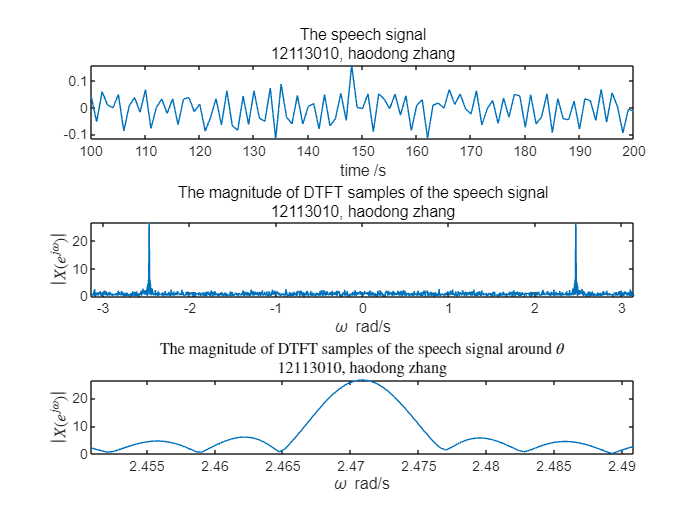

subplot(3,1,3);
plot(w,abs(X));
xlim([3146/4000*pi-0.02,3146/4000*pi+0.02]);
title(['The magnitude of DTFT samples of the speech signal around $\theta$' newline '12113010, haodong zhang'], 'Interpreter', 'latex');
xlabel('\omega rad/s');
ylabel('$\left | X(e^{j\omega})  \right | $', 'Interpreter', 'latex');

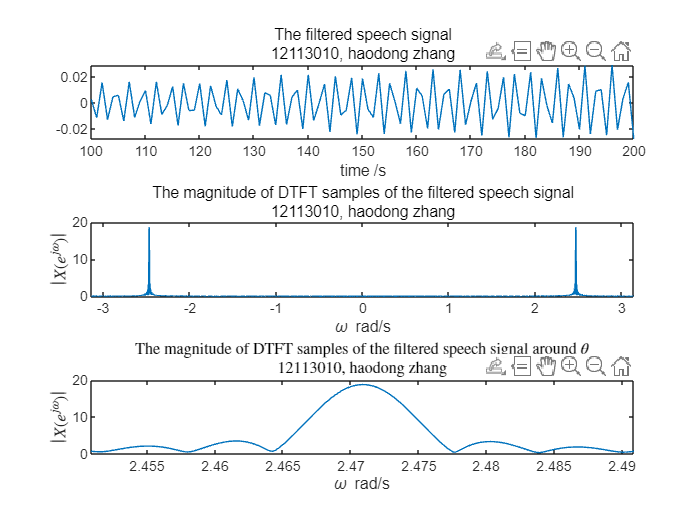

figure;
out = IIRfilter(pcm);
sound(out);
subplot(3,1,1);
plot(out);
xlim([100,200]);
title(['The filtered speech signal' newline '12113010, haodong zhang']);
xlabel('time /s');

[X,w] = DTFT(out(100:1100),20000);
subplot(3,1,2);
plot(w,abs(X));
xlim([-pi,pi]);
title(['The magnitude of DTFT samples of the filtered speech signal' newline '12113010, haodong zhang']);
xlabel('\omega rad/s');
ylabel('$\left | X(e^{j\omega})  \right | $', 'Interpreter', 'latex');
[Xmax,Imax] = max(abs(X));
theata = w(Imax);
subplot(3,1,3);
plot(w,abs(X));
xlim([3146/4000*pi-0.02,3146/4000*pi+0.02]);
title(['The magnitude of DTFT samples of the filtered speech signal around $\theta$' newline '12113010, haodong zhang'], 'Interpreter', 'latex');
xlabel('\omega rad/s');
ylabel('$\left | X(e^{j\omega})  \right | $', 'Interpreter', 'latex');

r = 0.9999999

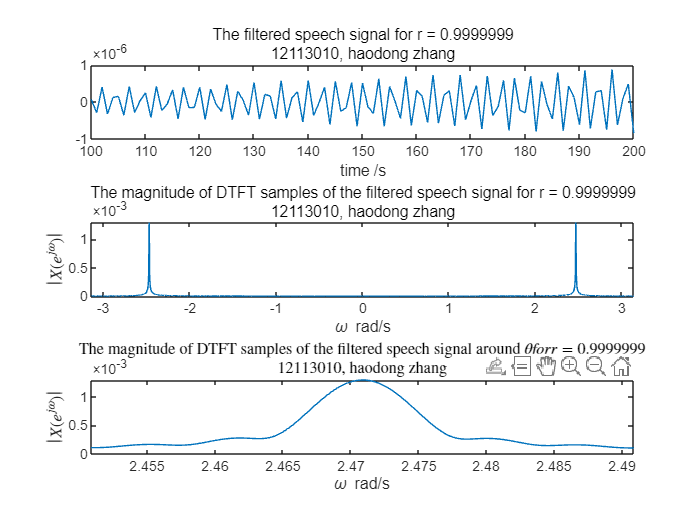

figure;
out = IIRfilter(pcm);
sound(out);
subplot(3,1,1);
plot(out);
xlim([100,200]);
title(['The filtered speech signal for r = 0.9999999' newline '12113010, haodong zhang']);
xlabel('time /s');

[X,w] = DTFT(out(100:1100),20000);
subplot(3,1,2);
plot(w,abs(X));
xlim([-pi,pi]);
title(['The magnitude of DTFT samples of the filtered speech signal for r = 0.9999999' newline '12113010, haodong zhang']);
xlabel('\omega rad/s');
ylabel('$\left | X(e^{j\omega})  \right | $', 'Interpreter', 'latex');

subplot(3,1,3);
plot(w,abs(X));
xlim([3146/4000*pi-0.02,3146/4000*pi+0.02]);
title(['The magnitude of DTFT samples of the filtered speech signal around $\theta for r = 0.9999999$' newline '12113010, haodong zhang'], 'Interpreter', 'latex');
xlabel('\omega rad/s');
ylabel('$\left | X(e^{j\omega})  \right | $', 'Interpreter', 'latex');

7.5+7.6

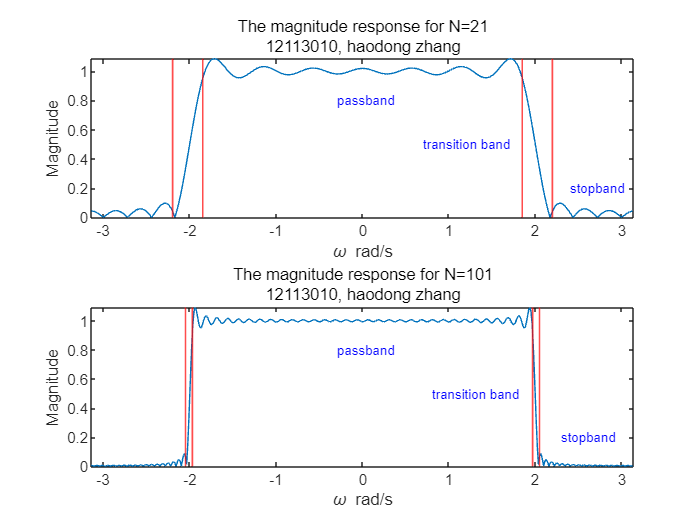

figure;
N1 = 21;
N2 = 101;
w = 2*pi*( (0:(512-1))/512 );
w = w - 2*pi*(w>=pi);
w = fftshift(w);
[h1,H1] = LPFtrunc(N1);
[h2,H2] = LPFtrunc(N2);

subplot(2,1,1);
plot(w,abs(H1));
title(['The magnitude response for N=21' newline '12113010, haodong zhang']);
xlabel('\omega rad/s');
ylabel('Magnitude');
xlim([-pi,pi])

hold on
xline(1.85, 'r', 'LineWidth', 1); 
hold on
xline(2.2, 'r', 'LineWidth', 1); 
hold on
xline(-1.85, 'r', 'LineWidth', 1); 
hold on
xline(-2.2, 'r', 'LineWidth', 1); 
hold on
text(2.4, 0.2, 'stopband', 'FontSize', 8, 'Color', 'blue');
hold on
text(-0.3, 0.8, 'passband', 'FontSize', 8, 'Color', 'blue');
hold on
text(0.7, 0.5, 'transition band', 'FontSize', 8, 'Color', 'blue');
hold off;

subplot(2,1,2);
plot(w,abs(H2));
title(['The magnitude response for N=101' newline '12113010, haodong zhang']);
xlabel('\omega rad/s');
ylabel('Magnitude');
xlim([-pi,pi])
hold on
xline(1.97, 'r', 'LineWidth', 1); 
hold on
xline(2.05, 'r', 'LineWidth', 1); 
hold on
xline(-1.97, 'r', 'LineWidth', 1); 
hold on
xline(-2.05, 'r', 'LineWidth', 1); 
hold on
text(2.3, 0.2, 'stopband', 'FontSize', 8, 'Color', 'blue');
hold on
text(-0.3, 0.8, 'passband', 'FontSize', 8, 'Color', 'blue');
hold on
text(0.8, 0.5, 'transition band', 'FontSize', 8, 'Color', 'blue');
hold off;

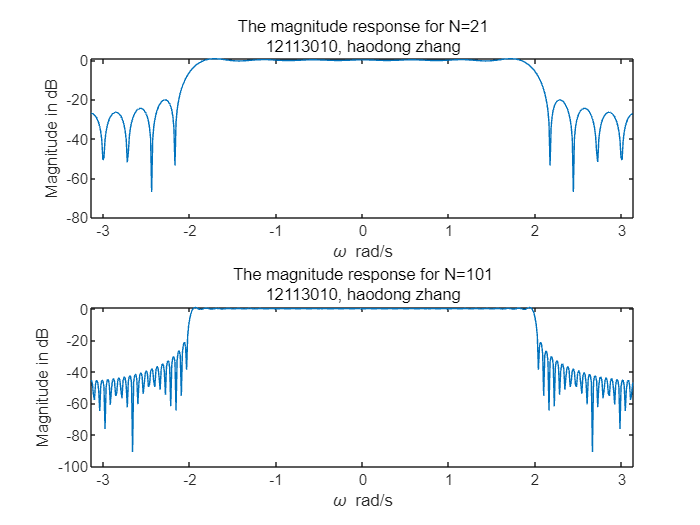


figure;
subplot(2,1,1);
plot(w,20*log10(abs(H1)));
title(['The magnitude response for N=21' newline '12113010, haodong zhang']);
xlabel('\omega rad/s');
ylabel('Magnitude in dB');
xlim([-pi,pi])

subplot(2,1,2);
plot(w,20*log10(abs(H2)));
title(['The magnitude response for N=101' newline '12113010, haodong zhang']);
xlabel('\omega rad/s');
ylabel('Magnitude in dB');
xlim([-pi,pi])

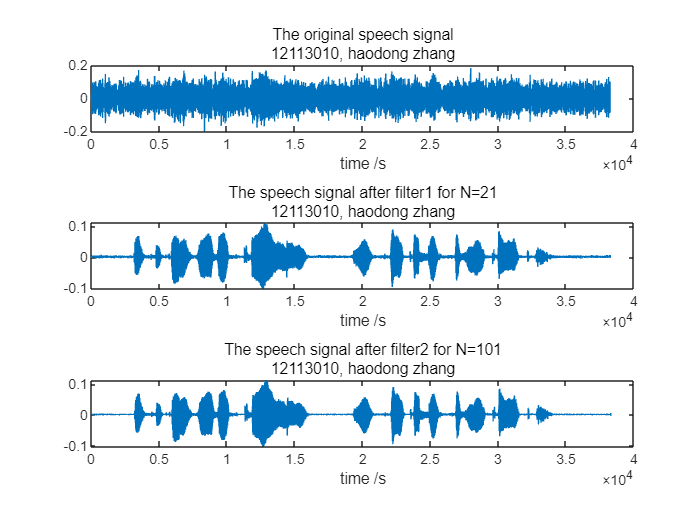

figure;
load nspeech2.mat;
sound(nspeech2);
subplot(3,1,1);
plot(nspeech2)
title(['The original speech signal' newline '12113010, haodong zhang']);
xlabel('time /s');
signal_after_filter1 = conv(nspeech2,h1);
subplot(3,1,2);
plot(signal_after_filter1);
title(['The speech signal after filter1 for N=21' newline '12113010, haodong zhang']);
xlabel('time /s');

signal_after_filter2 = conv(nspeech2,h2);
subplot(3,1,3);
plot(signal_after_filter2);
title(['The speech signal after filter2 for N=101' newline '12113010, haodong zhang']);
xlabel('time /s');

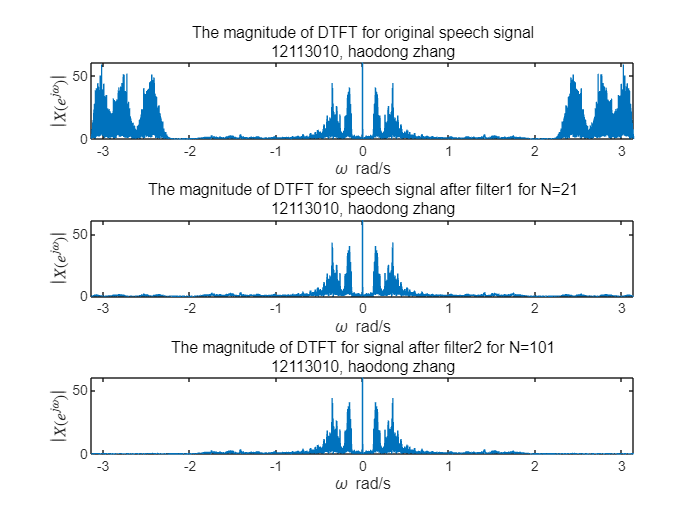

figure;
[X0,w] = DTFT(nspeech2,0);
[X1,w] = DTFT(signal_after_filter1,0);
[X2,w] = DTFT(signal_after_filter2,0);
subplot(3,1,1);
plot(w,abs(X0));
title(['The magnitude of DTFT for original speech signal' newline '12113010, haodong zhang']);
xlim([-pi,pi]);
xlabel('\omega rad/s');
ylabel('$\left | X(e^{j\omega})  \right | $', 'Interpreter', 'latex');

subplot(3,1,2);
plot(w,abs(X1));
title(['The magnitude of DTFT for speech signal after filter1 for N=21' newline '12113010, haodong zhang']);
xlim([-pi,pi]);
xlabel('\omega rad/s');
ylabel('$\left | X(e^{j\omega})  \right | $', 'Interpreter', 'latex');

subplot(3,1,3);
plot(w,abs(X2));
title(['The magnitude of DTFT for signal after filter2 for N=101' newline '12113010, haodong zhang']);
xlim([-pi,pi]);
xlabel('\omega rad/s');
ylabel('$\left | X(e^{j\omega})  \right | $', 'Interpreter', 'latex');

sound(3*signal_after_filter1);
sound(3*signal_after_filter2);